# Reporte - Robot Antropomórfico 3GDL

clc; clear; close all;

%% ==========================================================
%  BLOQUE 1: ANÁLISIS SIMBÓLICO (3 GDL)
%  ==========================================================
disp("=== ANÁLISIS SIMBÓLICO (3 GDL) ===")

=== ANÁLISIS SIMBÓLICO (3 GDL) ===


% Variables simbólicas
syms q1 q2 q3 l1 l2 l3 beta1 beta2 beta3 real 

% --- 1. Eslabón 1 ---
H1_0_sym = simplify( Hrz(q1) * Htz(l1+beta1) * Htx(0) * round(Hrx(90)) );
disp(">>> Matriz H1_0:"); disp(H1_0_sym);

>>> Matriz H1_0:


$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & \beta_{1}+l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% --- 2. Eslabón 2 ---
H2_1_sym = simplify( Hrz(q2) * Htz(beta2) * Htx(l2) * round(Hrx(0)) );
H2_0_sym = simplify( H1_0_sym * H2_1_sym );
disp(">>> Matriz H2_0:"); disp(H2_0_sym);

>>> Matriz H2_0:


$$\left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \sin\left(q_{1}\right) & \beta_{2}\,\sin\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & -\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-\beta_{2}\,\cos\left(q_{1}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & \beta_{1}+l_{1}+l_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% --- 3. Eslabón 3 ---
H3_2_sym = simplify( Hrz(q3) * Htz(beta3) * Htx(l3) * round(Hrx(0)) );
H3_0_sym = simplify( H2_0_sym * H3_2_sym );
Pf_sym = [H3_0_sym(1,4); H3_0_sym(2,4); H3_0_sym(3,4)];
disp(">>> Matriz Final H3_0:"); disp(H3_0_sym);

>>> Matriz Final H3_0:


$$\left(\begin{array}{cccc} \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{1}\right) & \beta_{2}\,\sin\left(q_{1}\right)+\beta_{3}\,\sin\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+l_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-l_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & -\cos\left(q_{1}\right) & l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-\beta_{3}\,\cos\left(q_{1}\right)-\beta_{2}\,\cos\left(q_{1}\right)+l_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-l_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)\\ \sin\left(q_{2}+q_{3}\right) & \cos\left(q_{2}+q_{3}\right) & 0 & \beta_{1}+l_{1}+l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% --- Cinemática Diferencial ---
disp("--- CINEMÁTICA DIFERENCIAL ---")

--- CINEMÁTICA DIFERENCIAL ---


J_sym = simplify(jacobian(Pf_sym, [q1, q2, q3]));
disp(">>> Matriz Jacobiana:");

>>> Matriz Jacobiana:


disp(J_sym);

$$\begin{array}{l} \left(\begin{array}{ccc} \beta_{2}\,\cos\left(q_{1}\right)+\beta_{3}\,\cos\left(q_{1}\right)-l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-l_{3}\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)+l_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -\cos\left(q_{1}\right)\,\sigma_{1} & -l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)\\ \beta_{2}\,\sin\left(q_{1}\right)+\beta_{3}\,\sin\left(q_{1}\right)+l_{2}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+l_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)-l_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right) & -\sin\left(q_{1}\right)\,\sigma_{1} & -l_{3}\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)\\ 0 & \sigma_{2}+l_{2}\,\cos\left(q_{2}\right) & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\\ \sigma_{2}=l_{3}\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

Det_J_sym = simplify(det(J_sym));
disp(">>> Determinante de la Matriz Jacobiana:");

>>> Determinante de la Matriz Jacobiana:


disp(Det_J_sym);

$$-l_{2}\,l_{3}\,\left(l_{3}\,\sin\left(q_{2}\right)\,{\cos\left(q_{3}\right)}^{2}+l_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\,\cos\left(q_{3}\right)-l_{3}\,\sin\left(q_{2}\right)+l_{2}\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\right)$$


%% ==========================================================
%  BLOQUE 2: ROBOT 1 (Configuración Base)
%  ==========================================================
disp("=== ROBOT 1: EVALUACIÓN Y GRÁFICAS ===")

=== ROBOT 1: EVALUACIÓN Y GRÁFICAS ===


% Parámetros del Robot 1
r1_l1 = 0.5; r1_l2 = 0.7; r1_l3 = 0.6;
r1_b1 = 0.1; r1_b2 = 0.1; r1_b3 = 0.1;
r1_q1 = deg2rad(25); r1_q2 = deg2rad(20); r1_q3 = deg2rad(30); 

sym_vars = [q1, q2, q3, l1, l2, l3, beta1, beta2, beta3];
vals_R1  = [r1_q1, r1_q2, r1_q3, r1_l1, r1_l2, r1_l3, r1_b1, r1_b2, r1_b3];
s_scale  = 0.20; 

% Evaluaciones Numéricas Robot 1
H1_R1 = double(subs(H1_0_sym, sym_vars, vals_R1)); S1_R1 = H1_R1(1:3, 4);
H2_R1 = double(subs(H2_0_sym, sym_vars, vals_R1)); S2_R1 = H2_R1(1:3, 4);
H3_R1 = double(subs(H3_0_sym, sym_vars, vals_R1)); Pf_R1 = H3_R1(1:3, 4);

disp("Punto Final Pf_R1 (X, Y, Z):"); disp(Pf_R1');

Punto Final Pf_R1 (X, Y, Z):
    1.0302    0.2597    1.2990



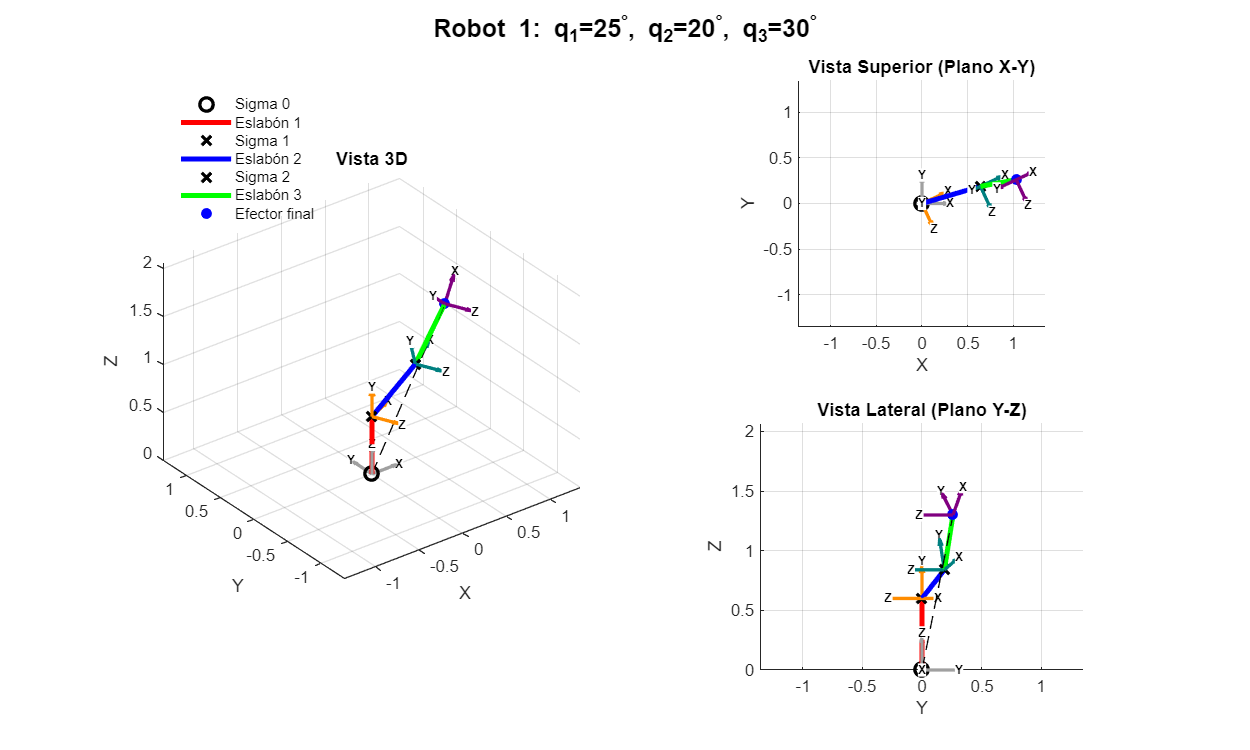


% --- Figura Robot 1 ---
L_max1 = r1_l1 + r1_l2 + r1_l3;
figure('Name', 'Robot 1 (3GDL)', 'Position', [50, 100, 1000, 600]);
sgtitle(['Robot 1: q_1=' num2str(rad2deg(r1_q1)) '^\circ, q_2=' num2str(rad2deg(r1_q2)) '^\circ, q_3=' num2str(rad2deg(r1_q3)) '^\circ'], 'FontWeight', 'bold');

% Vista 3D (Izquierda)
subplot(2, 2, [1, 3]);
h_leg = plotRobot(S1_R1, S2_R1, Pf_R1, H1_R1, H2_R1, H3_R1, L_max1);
view(3); title('Vista 3D');
% Agregamos la leyenda solicitada solo en la vista principal
legend([h_leg.orig, h_leg.e1, h_leg.s1, h_leg.e2, h_leg.s2, h_leg.e3, h_leg.pf], ...
       {'Sigma 0', 'Eslabón 1', 'Sigma 1', 'Eslabón 2', 'Sigma 2', 'Eslabón 3', 'Efector final'}, ...
       'Location', 'Northwest','Box','off','FontSize',9);

% Vista Superior (Arriba Derecha)
subplot(2, 2, 2);
plotRobot(S1_R1, S2_R1, Pf_R1, H1_R1, H2_R1, H3_R1, L_max1);
view(0, 90); title('Vista Superior (Plano X-Y)');

% Vista Lateral (Abajo Derecha)
subplot(2, 2, 4);
plotRobot(S1_R1, S2_R1, Pf_R1, H1_R1, H2_R1, H3_R1, L_max1);
view(90, 0); title('Vista Lateral (Plano Y-Z)');


% Cinemática Inversa Robot 1
[qi1, qi2, qi3] = cinv_R3gdl(r1_b1, r1_b2, r1_b3, r1_l1, r1_l2, r1_l3, Pf_R1(1), Pf_R1(2), Pf_R1(3));
disp("Cinemática Inversa R1 (q1, q2, q3):"); disp([qi1, qi2, qi3]);

Cinemática Inversa R1 (q1, q2, q3):
   25.0000   20.0000   30.0000





%% ==========================================================
%  BLOQUE 3: ROBOT 2 (Diferente Posición y Eslabones)
%  ==========================================================

disp("=== ROBOT 2: EVALUACIÓN Y GRÁFICAS ===")

=== ROBOT 2: EVALUACIÓN Y GRÁFICAS ===


% Parámetros exclusivos del Robot 2
r2_l1 = 0.65; r2_l2 = 0.5; r2_l3 = 0.5;
r2_b1 = 0.05; r2_b2 = 0.05; r2_b3 = 0.05;
r2_q1 = deg2rad(-30); r2_q2 = deg2rad(45); r2_q3 = deg2rad(60); 

vals_R2 = [r2_q1, r2_q2, r2_q3, r2_l1, r2_l2, r2_l3, r2_b1, r2_b2, r2_b3];

% Evaluaciones Numéricas Robot 2
H1_R2 = double(subs(H1_0_sym, sym_vars, vals_R2)); S1_R2 = H1_R2(1:3, 4);
H2_R2 = double(subs(H2_0_sym, sym_vars, vals_R2)); S2_R2 = H2_R2(1:3, 4);
H3_R2 = double(subs(H3_0_sym, sym_vars, vals_R2)); Pf_R2 = H3_R2(1:3, 4);

disp("Punto Final Pf_R2 (X, Y, Z):"); disp(Pf_R2');

Punto Final Pf_R2 (X, Y, Z):
    0.1441   -0.1987    1.5365



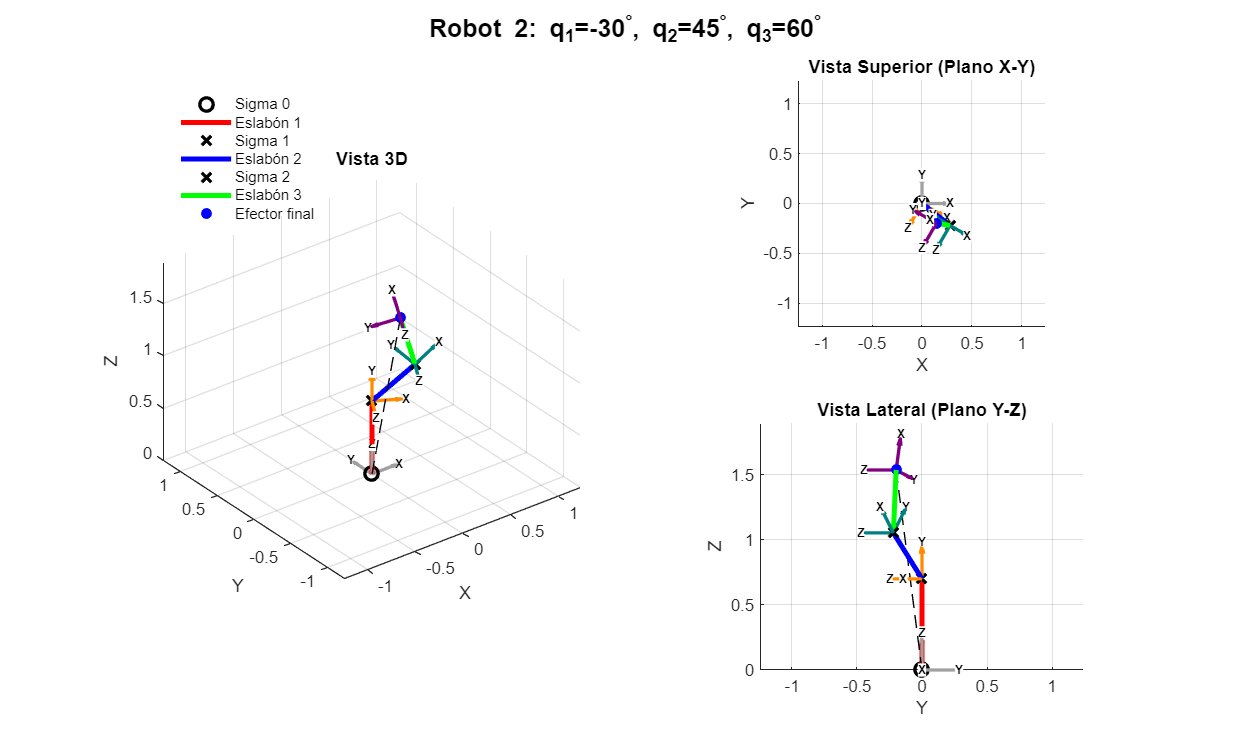


% --- Figura Robot 2 ---
L_max2 = r2_l1 + r2_l2 + r2_l3;
figure('Name', 'Robot 2 (3GDL)', 'Position', [100, 150, 1000, 600]);
sgtitle(['Robot 2: q_1=' num2str(rad2deg(r2_q1)) '^\circ, q_2=' num2str(rad2deg(r2_q2)) '^\circ, q_3=' num2str(rad2deg(r2_q3)) '^\circ'], 'FontWeight', 'bold');

subplot(2, 2, [1, 3]);
h_leg2 = plotRobot(S1_R2, S2_R2, Pf_R2, H1_R2, H2_R2, H3_R2, L_max2);
view(3); title('Vista 3D');
legend([h_leg2.orig, h_leg2.e1, h_leg2.s1, h_leg2.e2, h_leg2.s2, h_leg2.e3, h_leg2.pf], ...
       {'Sigma 0', 'Eslabón 1', 'Sigma 1', 'Eslabón 2', 'Sigma 2', 'Eslabón 3', 'Efector final'}, 'Location', 'Northwest','Box','off','FontSize',9);

subplot(2, 2, 2);
plotRobot(S1_R2, S2_R2, Pf_R2, H1_R2, H2_R2, H3_R2, L_max2);
view(0, 90); title('Vista Superior (Plano X-Y)');

subplot(2, 2, 4);
plotRobot(S1_R2, S2_R2, Pf_R2, H1_R2, H2_R2, H3_R2, L_max2);
view(90, 0); title('Vista Lateral (Plano Y-Z)');


% Cinemática Inversa Robot 2
[qi1, qi2, qi3] = cinv_R3gdl(r2_b1, r2_b2, r2_b3, r2_l1, r2_l2, r2_l3, Pf_R2(1), Pf_R2(2), Pf_R2(3));
disp("Cinemática Inversa R2 (q1, q2, q3):"); disp([qi1, qi2, qi3]);

Cinemática Inversa R2 (q1, q2, q3):
  -30.0000   45.0000   60.0000





%% ==========================================================
%  BLOQUE 4: ROBOT 3 (Configuración Extrema)
%  ==========================================================

disp("=== ROBOT 3: EVALUACIÓN Y GRÁFICAS ===")

=== ROBOT 3: EVALUACIÓN Y GRÁFICAS ===


% Parámetros exclusivos del Robot 3
r3_l1 = 0.6; r3_l2 = 0.55; r3_l3 = 0.25;
r3_b1 = 0; r3_b2 = 0; r3_b3 = 0;
r3_q1 = deg2rad(90); r3_q2 = deg2rad(-15); r3_q3 = deg2rad(-20); 

vals_R3 = [r3_q1, r3_q2, r3_q3, r3_l1, r3_l2, r3_l3, r3_b1, r3_b2, r3_b3];

% Evaluaciones Numéricas Robot 3
H1_R3 = double(subs(H1_0_sym, sym_vars, vals_R3)); S1_R3 = H1_R3(1:3, 4);
H2_R3 = double(subs(H2_0_sym, sym_vars, vals_R3)); S2_R3 = H2_R3(1:3, 4);
H3_R3 = double(subs(H3_0_sym, sym_vars, vals_R3)); Pf_R3 = H3_R3(1:3, 4);

disp("Punto Final Pf_R3 (X, Y, Z):"); disp(Pf_R3');

Punto Final Pf_R3 (X, Y, Z):
         0    0.7360    0.3143



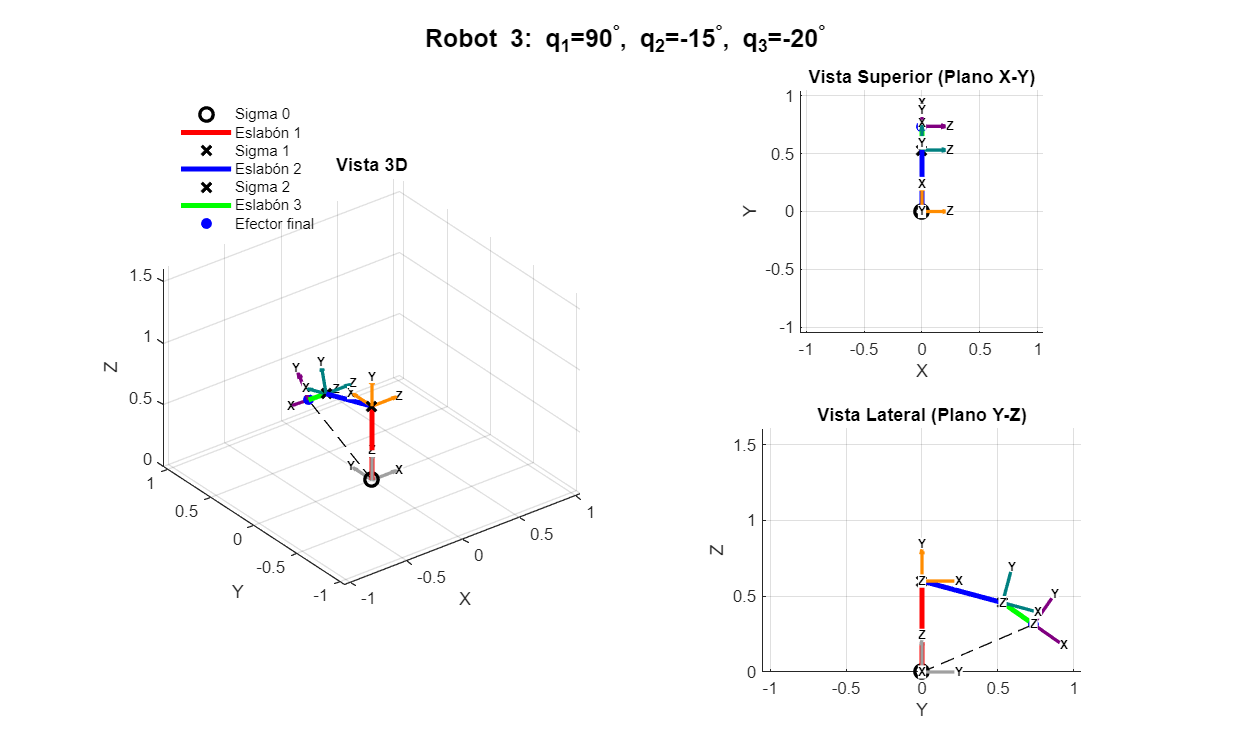


% --- Figura Robot 3 ---
L_max3 = r3_l1 + r3_l2 + r3_l3;
figure('Name', 'Robot 3 (3GDL)', 'Position', [150, 200, 1000, 600]);
sgtitle(['Robot 3: q_1=' num2str(rad2deg(r3_q1)) '^\circ, q_2=' num2str(rad2deg(r3_q2)) '^\circ, q_3=' num2str(rad2deg(r3_q3)) '^\circ'], 'FontWeight', 'bold');

subplot(2, 2, [1, 3]);
h_leg3 = plotRobot(S1_R3, S2_R3, Pf_R3, H1_R3, H2_R3, H3_R3, L_max3);
view(3); title('Vista 3D');
legend([h_leg3.orig, h_leg3.e1, h_leg3.s1, h_leg3.e2, h_leg3.s2, h_leg3.e3, h_leg3.pf], ...
       {'Sigma 0', 'Eslabón 1', 'Sigma 1', 'Eslabón 2', 'Sigma 2', 'Eslabón 3', 'Efector final'}, ...
       'Location', 'Northwest','Box','off','FontSize',9);

subplot(2, 2, 2);
plotRobot(S1_R3, S2_R3, Pf_R3, H1_R3, H2_R3, H3_R3, L_max3);
view(0, 90); title('Vista Superior (Plano X-Y)');

subplot(2, 2, 4);
plotRobot(S1_R3, S2_R3, Pf_R3, H1_R3, H2_R3, H3_R3, L_max3);
view(90, 0); title('Vista Lateral (Plano Y-Z)');


% Cinemática inversa Robot 3
[qi1, qi2, qi3] = cinv_R3gdl(r3_b1, r3_b2, r3_b3, r3_l1, r3_l2, r3_l3, Pf_R3(1), Pf_R3(2), Pf_R3(3), -1);
disp("Cinemática Inversa R3 (q1, q2, q3):"); disp([qi1, qi2, qi3]);

Cinemática Inversa R3 (q1, q2, q3):
   90.0000  -15.0000  -20.0000





%% ==========================================================
%  FUNCIONES LOCALES
%  ==========================================================

function h = plotRobot(S1, S2, Pf, H1, H2, H3, L_max)
    % plotRobot: Dibuja la estructura, ajusta la caja y escala los ejes automáticamente
    hold on; grid on; axis equal;
    
    % Dibujo de componentes
    h.orig = plot3(0, 0, 0, 'ko', 'MarkerSize', 8, 'LineWidth', 2);
    h.e1   = plot3([0, S1(1)], [0, S1(2)], [0, S1(3)], 'r', 'LineWidth', 3);
    h.s1   = plot3(S1(1), S1(2), S1(3), 'kx', 'MarkerSize', 8, 'LineWidth', 2);
    h.e2   = plot3([S1(1), S2(1)], [S1(2), S2(2)], [S1(3), S2(3)], 'b', 'LineWidth', 3);
    h.s2   = plot3(S2(1), S2(2), S2(3), 'kx', 'MarkerSize', 8, 'LineWidth', 2);
    h.e3   = plot3([S2(1), Pf(1)], [S2(2), Pf(2)], [S2(3), Pf(3)], 'g', 'LineWidth', 3);
    h.pf   = plot3(Pf(1), Pf(2), Pf(3), 'bo', 'MarkerFaceColor', 'b');
    
    plot3([0, Pf(1)], [0, Pf(2)], [0, Pf(3)], 'k--'); 
    
    % --- 1. LÍMITES DINÁMICOS (Caja de simulación) ---
    lim_xy = L_max * 0.75; 
    lim_z  = L_max * 1.15; 
    xlim([-lim_xy, lim_xy]); ylim([-lim_xy, lim_xy]); zlim([0, lim_z]); 
    
    % --- 2. ESCALA DINÁMICA DE LOS EJES ---
    scale = L_max * 0.15; 
    
    q0 = drawFrame(eye(4), scale); q0.Color = '#A0A0A0';
    q1 = drawFrame(H1, scale);     q1.Color = '#FF8C00';
    q2 = drawFrame(H2, scale);     q2.Color = '#008080';
    q3 = drawFrame(H3, scale);     q3.Color = '#800080';
    
    xlabel('X'); ylabel('Y'); zlabel('Z');
end